## **Espace de solutions**

### **Recuperation des solutions calculées dans le fichier ***Config_Robot_Redondant_Point*

On définit tout d'abord les variables du code puis l'espace de solutions sans conditions de filtrage pour atteindre le point cible est recupéré pour ensuite afficher les differentes configuration articulaires possibles en radian, et en degres

% Charger les solutions depuis le fichier
load('solutions.mat');
% Convertir les angles de radians en degrés et afficher les résultats
all_solutions_deg = rad2deg(all_solutions(:, 1:5));

% Convertir les angles en radians et ajuster les angles à l'intervalle [-180, 180]
all_solutions_deg = mod(all_solutions_deg + 180, 360) - 180;

% Afficher toutes les configurations trouvées en radian
disp('Configurations possibles du robot en radians pour la position désirée :');

Configurations possibles du robot en radians pour la position désirée :



fprintf('| %-9s | %-9s | %-9s | %-9s | %-9s | %-11s | %-11s |\n', 'Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5', 'X_calculé', 'Y_calculé');

| Theta1    | Theta2    | Theta3    | Theta4    | Theta5    | X_calculé   | Y_calculé   |


disp('__________________________________________________________________________________________');

__________________________________________________________________________________________


for i = 1:size(all_solutions_deg, 1)
    fprintf('| %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-11.0f | %-11.0f |\n', all_solutions(i,:));
end

| 1.5977    | 5.4472    | 1.2975    | 4.5703    | 6.1819    | 5           | 7           |
| 1.3366    | 5.0590    | 0.7578    | 6.2573    | 1.2869    | 5           | 7           |
| 1.1092    | 6.0548    | 1.0444    | 5.3933    | 4.8902    | 5           | 7           |
| 1.2059    | 5.8900    | 5.1396    | 1.3690    | 0.8812    | 5           | 7           |
| 1.2571    | 5.9680    | 4.8484    | 1.4533    | 0.7559    | 5           | 7           |
| 0.6827    | 0.5802    | 0.6421    | 5.2593    | 5.1221    | 5           | 7           |
| 0.4045    | 0.4948    | 1.2960    | 4.2394    | 1.1731    | 5           | 7           |
| 1.2625    | 6.0836    | 0.8676    | 4.9142    | 5.4874    | 5           | 7           |
| 1.2743    | 5.9475    | 4.7332    | 1.7587    | 0.3315    | 5           | 7           |
| 0.3624    | 0.6686    | 5.4347    | 0.9347    | 1.1322    | 5           | 7           |
| 0.7433    | 0.3513    | 0.7338    | 5.6034    | 4.7349    | 5           | 7           |
| 1.2098  

disp('__________________________________________________________________________________________');

__________________________________________________________________________________________


    

% Convertion des angles de radians en degrés et afficher les résultats
all_solutions_deg = rad2deg(all_solutions(:, 1:5));
% % Afficher toutes les configurations trouvées en degrrs
% disp('Configurations possibles du robot en degres pour la position désirée :');
% disp('    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé')
% disp([all_solutions_deg, all_solutions(:, 6:7)]);
 

% Convertir les angles en radians et ajuster les angles à l'intervalle [-180, 180]
all_solutions_deg = mod(all_solutions_deg + 180, 360) - 180;
% Afficher toutes les configurations trouvées en degrés avec centrage des titres
disp('Configurations possibles du robot en degrés pour la position désirée :');

Configurations possibles du robot en degrés pour la position désirée :


fprintf('| %-9s | %-9s | %-9s | %-9s | %-9s | %-11s | %-11s |\n', 'Theta1°', 'Theta2°', 'Theta3°', 'Theta4°', 'Theta5°', 'X_calculé', 'Y_calculé');

| Theta1°   | Theta2°   | Theta3°   | Theta4°   | Theta5°   | X_calculé   | Y_calculé   |


disp('_________________________________________________________________________________________');

_________________________________________________________________________________________


for i = 1:size(all_solutions_deg, 1)
    fprintf('| %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-11.0f | %-11.0f |\n', all_solutions_deg(i,:), all_solutions(i, 6:7));
end

| 91.5442   | -47.8991  | 74.3407   | -98.1434  | -5.8037   | 5           | 7           |
| 76.5801   | -70.1380  | 43.4172   | -1.4845   | 73.7345   | 5           | 7           |
| 63.5553   | -13.0883  | 59.8408   | -50.9878  | -79.8149  | 5           | 7           |
| 69.0955   | -22.5283  | -65.5204  | 78.4391   | 50.4887   | 5           | 7           |
| 72.0282   | -18.0594  | -82.2074  | 83.2693   | 43.3071   | 5           | 7           |
| 39.1139   | 33.2411   | 36.7905   | -58.6658  | -66.5241  | 5           | 7           |
| 23.1782   | 28.3504   | 74.2547   | -117.1016 | 67.2125   | 5           | 7           |
| 72.3373   | -11.4363  | 49.7101   | -78.4356  | -45.5924  | 5           | 7           |
| 73.0139   | -19.2351  | -88.8059  | 100.7677  | 18.9948   | 5           | 7           |
| 20.7622   | 38.3074   | -48.6132  | 53.5523   | 64.8704   | 5           | 7           |
| 42.5863   | 20.1293   | 42.0454   | -38.9466  | -88.7088  | 5           | 7           |
| 69.3147 

disp('_________________________________________________________________________________________');

_________________________________________________________________________________________


### **Variation de theta pour chaque solution**

% Définir le nombre total de solutions
num_solutions = size(all_solutions, 1);
% Définir le nombre de lignes et de colonnes pour la grille
num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
num_cols = 2; % Nombre de colonnes pour afficher les graphiques
% Définir les positions des subplots
position = reshape(1:num_rows*num_cols, num_cols, num_rows).';

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
all_solutions_deg = rad2deg(all_solutions(:, 1:5));
all_solutions_deg = mod(all_solutions_deg + 180, 360) - 180;

% Créer une nouvelle figure
figure;

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']); % Modification de l'étiquette en degrés
    grid on;

    hold on; % Garder le graphique actif pour ajouter les données de chaque solution

    % Tracer les valeurs des angles d'articulation pour chaque solution
    for i = 1:num_solutions
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = all_solutions_deg(i, joint);

        % Tracer l'angle d'articulation pour cette solution
        plot(i, theta_deg, '+', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k','HandleVisibility', 'off');
    end

    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = all_solutions_deg(:, joint); % Les données y sont les angles d'articulation déjà ajustés

    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 1000); % 1000 points entre le premier et le dernier index

    % Calculer les valeurs interpolées
    interpolated_1 = interp1(x_data, y_data, finer_x, 'spline');
    interpolated_2 = interp1(x_data, y_data, finer_x, 'linear');

    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_1, 'r-', 'LineWidth', 1, 'DisplayName', 'Interpolation Spline');
    plot(finer_x, interpolated_2, 'k-', 'LineWidth', 1, 'DisplayName', 'Interpolation Lineaire');

    % Trouver la valeur maximale et minimale de theta pour cet angle d'articulation
    max_theta = max(all_solutions_deg(:, joint));
    min_theta = min(all_solutions_deg(:, joint));
    
    % Ajouter du texte à la position souhaitée
    text(-1, max_theta, ['Max: ', num2str(max_theta)], 'Color', 'blue', 'FontSize', 8);
    text(-1, min_theta, ['Min: ', num2str(min_theta)], 'Color', 'blue', 'FontSize', 8);
    disp(['Pour theta', num2str(joint), ', Theta max : ', num2str(max_theta), ', Theta min : ', num2str(min_theta)]);

    % Tracer une droite représentant la valeur maximale de theta pour cet angle d'articulation
    plot([1, num_solutions], [max_theta, max_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Max Theta', num2str(joint)]);

    % Tracer une droite représentant la valeur minimale de theta pour cet angle d'articulation
    plot([1, num_solutions], [min_theta, min_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Min Theta', num2str(joint)]);
      
end

Pour theta1, Theta max : 117.1972, Theta min : -23.8831
Pour theta2, Theta max : 88.8992, Theta min : -70.138
Pour theta3, Theta max : 118.1627, Theta min : -92.6305
Pour theta4, Theta max : 100.7677, Theta min : -117.1016
Pour theta5, Theta max : 117.8045, Theta min : -88.7088


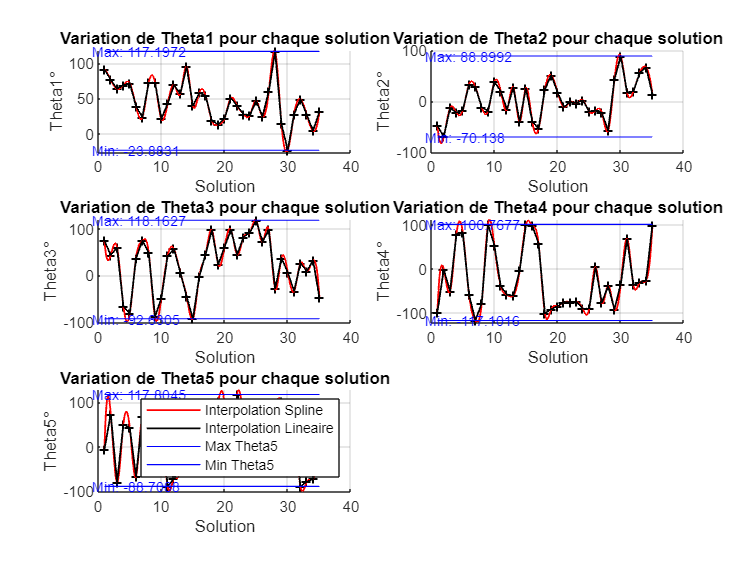


% Légende
legend('show');

#### Courbe des angles pour chaque solution - interpolation

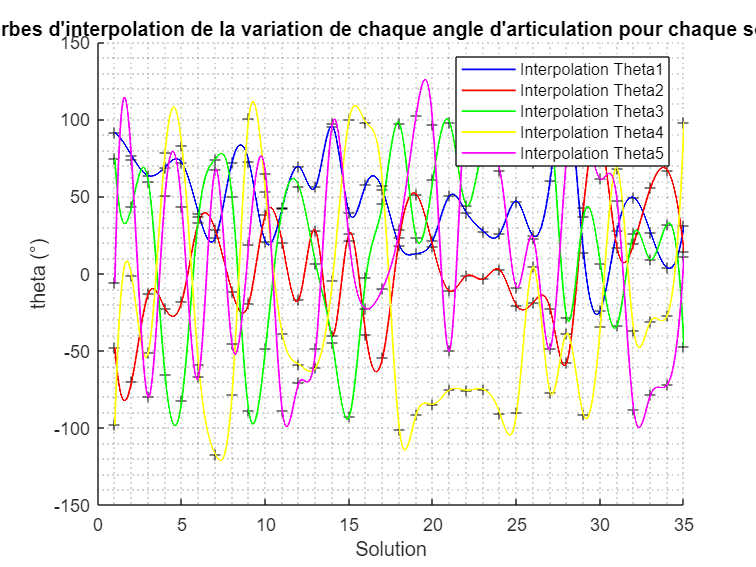

%Courbe de chaque angles 
% Créer une nouvelle figure
figure;

% Titre et étiquettes des axes
title('Courbes d''interpolation de la variation de chaque angle d''articulation pour chaque solution');
xlabel('Solution');
ylabel('theta (°)');
grid minor;
hold on; % Garder le graphique actif pour ajouter les données de chaque solution

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Tracer les valeurs des angles d'articulation pour chaque solution en convertissant les radians en degrés
    for i = 1:num_solutions
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = all_solutions_deg(i, joint);
        % Tracer l'angle d'articulation pour cette solution avec un marqueur plein
        plot(i, theta_deg, '+', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');

    end
    
    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = all_solutions_deg(:, joint); % Les données y sont les angles d'articulation convertis en degrés
    
    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 10000); % 1000 points entre le premier et le dernier index
    
    % Calculer les valeurs interpolées
    interpolated_y = interp1(x_data, y_data, finer_x, 'spline');
    
    % Couleurs pour chaque angle d'articulation
    colors = ['b', 'r', 'g', 'y', 'm'];
    
    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_y, '-', 'DisplayName', ['Interpolation Theta', num2str(joint)], 'LineWidth', 1, 'Color', colors(joint));
end
        
legend("show")  

#### Positions des articulations pour chaque solution

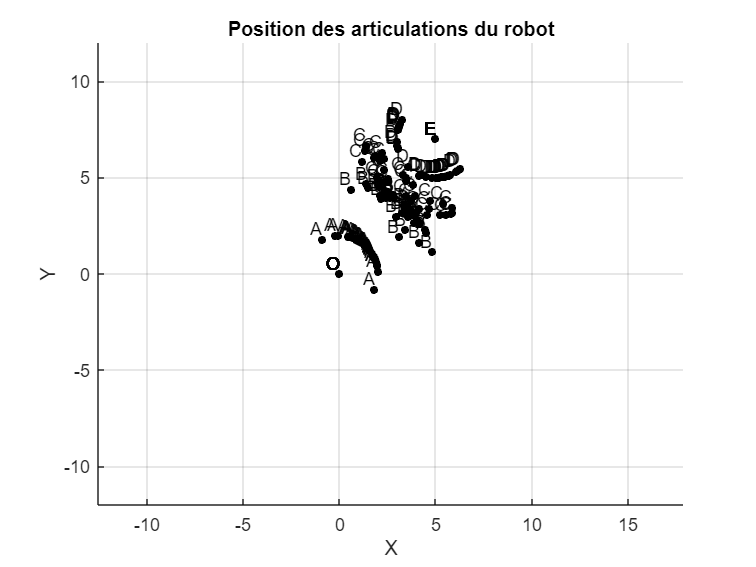

% Créer un graphique distinct pour les articulations du robot
figure;


hold on; % Garder le graphique actif pour ajouter les données de chaque solution


% Visualisation des configurations du robot
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    theta5 = all_solutions(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations
    % Ajouter les noms des articulations
    text([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], {'O', 'A', 'B', 'C', 'D', 'E'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end 
grid on;

% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot');
xlabel('X');
ylabel('Y');

#### Graphique separe pour chaque articulation

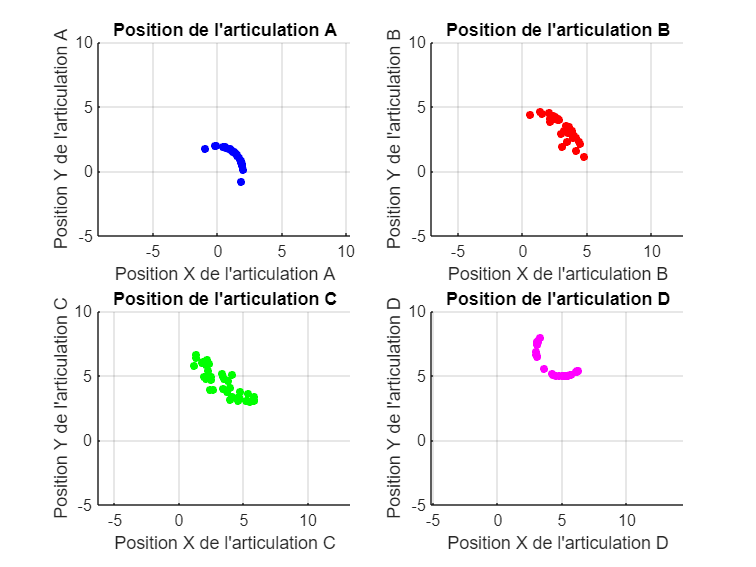

% Créer un graphique distinct pour chaque articulation
figure;

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution
A_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire l'angle d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
end
scatter(A_positions(:, 1), A_positions(:, 2), 20, 'b', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution
B_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    
    % Calculer la position de l'articulation B pour cette solution
    B = A_positions(i, :) + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
end
scatter(B_positions(:, 1), B_positions(:, 2), 20, 'r', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution
C_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    
    % Calculer la position de l'articulation C pour cette solution
    C = B_positions(i, :) + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
end
scatter(C_positions(:, 1), C_positions(:, 2), 20, 'g', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution
D_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    
    % Calculer la position de l'articulation D pour cette solution
    D = C_positions(i, :) + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
end
scatter(D_positions(:, 1), D_positions(:, 2), 20, 'm', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;